### **Renombrar variables**

nombres_variables = ["SepalLength", "SepalWidth", "PetalLength", "PetalWidth", "Species"];
iris.Properties.VariableNames = nombres_variables;

iris_copy = iris;

rng(769) % Semilla para reproducibilidad

### Entrenamiento SVMs

% Definir hiperparámetros
boxConstraint = [1, 3, 5];
kernelFunctions = {'linear', 'gaussian', 'polynomial'};
number_reps = 3;

% Generar combinaciones
[BC, KF] = ndgrid(boxConstraint, 1:length(kernelFunctions));
combinaciones = [BC(:), KF(:)];
numCombinaciones = size(combinaciones, 1);

% Configuración inicial
K = height(iris_copy);  % LOOCV
variablesContinuas = [1, 2, 3, 4];
clasesUnicas = categories(categorical(iris_copy{:,5}));
NumClases = length(clasesUnicas);

% Inicializar almacenamiento
svmModels = cell(1, numCombinaciones, number_reps);
metricsSVM = struct('Accuracy', zeros(1, numCombinaciones, number_reps), ...
                    'Precision', zeros(1, numCombinaciones, number_reps), ...
                    'Specificity', zeros(1, numCombinaciones, number_reps), ...
                    'Recall', zeros(1, numCombinaciones, number_reps), ...
                    'F1Score', zeros(1, numCombinaciones, number_reps));

resultadosBinariosSVM = cell(numCombinaciones, number_reps);
prediccionesShuffleSVM = cell(numCombinaciones, number_reps);

% Estructura adicional para métricas por clase
metricsClassSVM = struct();
metricsClassSVM.Recall = zeros(numCombinaciones, NumClases, number_reps);
metricsClassSVM.Precision = zeros(numCombinaciones, NumClases, number_reps);
metricsClassSVM.Specificity = zeros(numCombinaciones, NumClases, number_reps);
metricsClassSVM.Accuracy = zeros(numCombinaciones, NumClases, number_reps);
metricsClassSVM.F1Score = zeros(numCombinaciones, NumClases, number_reps);

% ======= ENTRENAMIENTO Y EVALUACIÓN =======
for modelIdx = 1:numCombinaciones
    c = combinaciones(modelIdx, 1);
    kernelIdx = combinaciones(modelIdx, 2);
    kernel = kernelFunctions{kernelIdx};

    for rep = 1:number_reps
        Y_true_all = strings(K,1);
        Y_pred_all = strings(K,1);
        aciertosModelo = zeros(K,1);

        cv = cvpartition(K, 'KFold', K);

        for fold = 1:K
            trainData = iris_copy(training(cv, fold), :);
            testData = iris_copy(test(cv, fold), :);

            % Normalizar
            media = mean(trainData{:, variablesContinuas});
            desviacion = std(trainData{:, variablesContinuas});
            trainData{:, variablesContinuas} = (trainData{:, variablesContinuas} - media) ./ desviacion;
            testData{:, variablesContinuas} = (testData{:, variablesContinuas} - media) ./ desviacion;

            % Extraer datos
            X_train = trainData{:, variablesContinuas};
            Y_train = trainData{:, 5};
            X_test = testData{:, variablesContinuas};
            Y_test = testData{:, 5};

            % Entrenar modelo SVM multiclase
            template = templateSVM('BoxConstraint', c, 'KernelFunction', kernel);
            modeloSVM = fitcecoc(X_train, Y_train, 'Learners', template, 'Coding', 'onevsone');

            % Predecir
            prediction = predict(modeloSVM, X_test);

            % Acumular
            Y_true_all(fold) = Y_test;
            Y_pred_all(fold) = prediction;
            aciertosModelo(fold) = double(prediction == Y_test);
        end

        % ---- Shuffle y creación de folds ----
        tablaResultados = table(string(Y_true_all), string(Y_pred_all), ...
            'VariableNames', {'Real', 'Prediccion'});

        rng(123 + modelIdx + rep);  % Semilla reproducible por combinación y repetición
        tablaResultadosShuffle = tablaResultados(randperm(height(tablaResultados)), :);

        numFoldsShuffle = 10;
        foldSize = height(tablaResultadosShuffle) / numFoldsShuffle;
        foldsShuffle = cell(numFoldsShuffle, 1);

        for i = 1:numFoldsShuffle
            idxStart = (i - 1) * foldSize + 1;
            idxEnd = i * foldSize;
            foldsShuffle{i} = tablaResultadosShuffle(idxStart:idxEnd, :);
        end

        prediccionesShuffleSVM{modelIdx, rep} = foldsShuffle;

        % ---- Cálculo de métricas desde folds ----
        recallTemp = [];
        precisionTemp = [];
        specificityTemp = [];
        accuracyTemp = [];
        f1Temp = [];

        for foldIdx = 1:numFoldsShuffle
            datosFold = foldsShuffle{foldIdx};
            Y_true_fold = categorical(datosFold.Real);
            Y_pred_fold = categorical(datosFold.Prediccion);

            CM_fold = confusionmat(Y_true_fold, Y_pred_fold, 'Order', clasesUnicas);

            recallVec = zeros(NumClases, 1);
            precisionVec = zeros(NumClases, 1);
            specificityVec = zeros(NumClases, 1);
            accuracyVec = zeros(NumClases, 1);
            f1Vec = zeros(NumClases, 1);

            for classIdx = 1:NumClases
                [recall, specificity, precision, ~, accuracy, f1score] = performanceIndexes(CM_fold, classIdx);
                recallVec(classIdx)      = recall;
                precisionVec(classIdx)   = precision;
                specificityVec(classIdx) = specificity;
                accuracyVec(classIdx)    = accuracy;
                f1Vec(classIdx)           = f1score;
            end

            recallTemp = [recallTemp; recallVec'];
            precisionTemp = [precisionTemp; precisionVec'];
            specificityTemp = [specificityTemp; specificityVec'];
            accuracyTemp = [accuracyTemp; accuracyVec'];
            f1Temp = [f1Temp; f1Vec'];
        end

        % Guardar promedio macro
        metricsSVM.Accuracy(1, modelIdx, rep)    = mean(mean(accuracyTemp,2));
        metricsSVM.Recall(1, modelIdx, rep)      = mean(mean(recallTemp,2));
        metricsSVM.Precision(1, modelIdx, rep)   = mean(mean(precisionTemp,2));
        metricsSVM.Specificity(1, modelIdx, rep) = mean(mean(specificityTemp,2));
        metricsSVM.F1Score(1, modelIdx, rep)     = mean(mean(f1Temp,2));

        % Guardar por clase (media entre folds)
        metricsClassSVM.Recall(modelIdx, :, rep)      = mean(recallTemp,1);
        metricsClassSVM.Precision(modelIdx, :, rep)   = mean(precisionTemp,1);
        metricsClassSVM.Specificity(modelIdx, :, rep) = mean(specificityTemp,1);
        metricsClassSVM.Accuracy(modelIdx, :, rep)    = mean(accuracyTemp,1);
        metricsClassSVM.F1Score(modelIdx, :, rep)     = mean(f1Temp,1);

        % Guardar binarios y modelo
        resultadosBinariosSVM{modelIdx, rep} = aciertosModelo;
        svmModels{1, modelIdx, rep} = modeloSVM;
    end
end


% ================== MÉTRICAS PROMEDIO Y DESVIACIÓN POR COMBINACIÓN ==================
Mean_RecallSVM_final       = squeeze(mean(metricsSVM.Recall, 3));
Mean_SpecificitySVM_final  = squeeze(mean(metricsSVM.Specificity, 3));
Mean_PrecisionSVM_final    = squeeze(mean(metricsSVM.Precision, 3));
Mean_ACCSVM_final          = squeeze(mean(metricsSVM.Accuracy, 3));
Mean_F1ScoreSVM_final      = squeeze(mean(metricsSVM.F1Score, 3));

Std_RecallSVM_final        = squeeze(std(metricsSVM.Recall, 0, 3));
Std_SpecificitySVM_final   = squeeze(std(metricsSVM.Specificity, 0, 3));
Std_PrecisionSVM_final     = squeeze(std(metricsSVM.Precision, 0, 3));
Std_ACCSVM_final           = squeeze(std(metricsSVM.Accuracy, 0, 3));
Std_F1ScoreSVM_final       = squeeze(std(metricsSVM.F1Score, 0, 3));

#### Función para generar tabla

function mostrarResumenSVM(combinaciones, kernelFunctions, ...
    Mean_ACC, Std_ACC, ...
    Mean_Recall, Std_Recall, ...
    Mean_Precision, Std_Precision, ...
    Mean_Specificity, Std_Specificity, ...
    Mean_F1, Std_F1)

    numCombinaciones = size(combinaciones, 1);

    % Inicializar columnas
    modelo = strings(numCombinaciones, 1);
    BC = zeros(numCombinaciones, 1);
    kernel = strings(numCombinaciones, 1);

    Accuracy = zeros(numCombinaciones, 1);
    Accuracy_std = strings(numCombinaciones, 1);
    Recall = zeros(numCombinaciones, 1);
    Recall_std = strings(numCombinaciones, 1);
    Precision = zeros(numCombinaciones, 1);
    Precision_std = strings(numCombinaciones, 1);
    Specificity = zeros(numCombinaciones, 1);
    Specificity_std = strings(numCombinaciones, 1);
    F1 = zeros(numCombinaciones, 1);
    F1_std = strings(numCombinaciones, 1);

    % Llenar los vectores
        for i = 1:numCombinaciones
        modelo(i) = sprintf("SVM %d", i);
        BC(i) = combinaciones(i, 1);
        kernel(i) = kernelFunctions{combinaciones(i, 2)};

        Accuracy(i) = Mean_ACC(i);
        Accuracy_std(i) = strrep(sprintf('%.2e', Std_ACC(i)), 'e', ' × 10^');
        Recall(i) = Mean_Recall(i);
        Recall_std(i) = strrep(sprintf('%.2e', Std_Recall(i)), 'e', ' × 10^');
        Precision(i) = Mean_Precision(i);
        Precision_std(i) = strrep(sprintf('%.2e', Std_Precision(i)), 'e', ' × 10^');
        Specificity(i) = Mean_Specificity(i);
        Specificity_std(i) = strrep(sprintf('%.2e', Std_Specificity(i)), 'e', ' × 10^');
        F1(i) = Mean_F1(i);
        F1_std(i) = strrep(sprintf('%.2e', Std_F1(i)), 'e', ' × 10^');
    end


    % Crear y mostrar la tabla
    tabla = table(modelo, BC, kernel, ...
        Accuracy, Accuracy_std, ...
        Recall, Recall_std, ...
        Precision, Precision_std, ...
        Specificity, Specificity_std, ...
        F1, F1_std);

    disp(tabla);
end

mostrarResumenSVM(combinaciones, kernelFunctions, ...
    Mean_ACCSVM_final, Std_ACCSVM_final, ...
    Mean_RecallSVM_final, Std_RecallSVM_final, ...
    Mean_PrecisionSVM_final, Std_PrecisionSVM_final, ...
    Mean_SpecificitySVM_final, Std_SpecificitySVM_final, ...
    Mean_F1ScoreSVM_final, Std_F1ScoreSVM_final);

    modelo     BC       kernel       Accuracy     Accuracy_std      Recall       Recall_std       Precision     Precision_std     Specificity    Specificity_std      F1           F1_std     
    _______    __    ____________    ________    _______________    _______    _______________    _________    _______________    ___________    _______________    _______    _______________

    "SVM 1"    1     "linear"        0.96889     "0.00 × 10^+00"    0.95447    "9.80 × 10^-04"      0.9539     "9.02 × 10^-04"      0.97622      "1.53 × 10^-04"    0.94966    

function mostrarResumenSVMPorClase(combinaciones, clasesUnicas, kernelFunctions, metricsClassSVM)
    numModelos = size(combinaciones, 1);
    numClases = length(clasesUnicas);
    numFilas = numModelos * numClases;

    modelo = strings(numFilas, 1);
    kernel = strings(numFilas, 1);
    clase = strings(numFilas, 1);

    % Inicializar columnas métricas
    Accuracy     = zeros(numFilas, 1);
    Accuracy_std = strings(numFilas, 1);
    Recall       = zeros(numFilas, 1);
    Recall_std   = strings(numFilas, 1);
    Precision    = zeros(numFilas, 1);
    Precision_std = strings(numFilas, 1);
    Specificity  = zeros(numFilas, 1);
    Specificity_std = strings(numFilas, 1);
    F1           = zeros(numFilas, 1);
    F1_std       = strings(numFilas, 1);

    idx = 1;
    for modelIdx = 1:numModelos
        for classIdx = 1:numClases
            modelo(idx) = sprintf("SVM %d", modelIdx);
            kernel(idx) = kernelFunctions{combinaciones(modelIdx, 2)};
            clase(idx) = clasesUnicas{classIdx};

            % Extraer métricas por repetición
            accVals  = squeeze(metricsClassSVM.Accuracy(modelIdx, classIdx, :));
            recVals  = squeeze(metricsClassSVM.Recall(modelIdx, classIdx, :));
            precVals = squeeze(metricsClassSVM.Precision(modelIdx, classIdx, :));
            specVals = squeeze(metricsClassSVM.Specificity(modelIdx, classIdx, :));
            f1Vals   = squeeze(metricsClassSVM.F1Score(modelIdx, classIdx, :));

            % Calcular medias
            Accuracy(idx)    = mean(accVals);
            Recall(idx)      = mean(recVals);
            Precision(idx)   = mean(precVals);
            Specificity(idx) = mean(specVals);
            F1(idx)          = mean(f1Vals);

            % Formatear std con notación base 10
            Accuracy_std(idx)     = formatStd(accVals);
            Recall_std(idx)       = formatStd(recVals);
            Precision_std(idx)    = formatStd(precVals);
            Specificity_std(idx)  = formatStd(specVals);
            F1_std(idx)           = formatStd(f1Vals);

            idx = idx + 1;
        end
    end

    % Crear tabla
    tabla = table(modelo, kernel, clase, ...
        Accuracy, Accuracy_std, ...
        Recall, Recall_std, ...
        Precision, Precision_std, ...
        Specificity, Specificity_std, ...
        F1, F1_std);

    disp(tabla);
end

function s = formatStd(values)
    val = std(values);
    if val == 0
        s = "0";
    else
        s = strrep(sprintf('%.2e', val), 'e', ' × 10^');
    end
end


mostrarResumenSVMPorClase(combinaciones, clasesUnicas, kernelFunctions, metricsClassSVM);

    modelo        kernel             clase          Accuracy     Accuracy_std      Recall       Recall_std       Precision     Precision_std     Specificity    Specificity_std      F1           F1_std     
    _______    ____________    _________________    ________    _______________    _______    _______________    _________    _______________    ___________    _______________    _______    _______________

    "SVM 1"    "linear"        "Iris-setosa"              1     "0"                      1    "0"                       1     "0"                

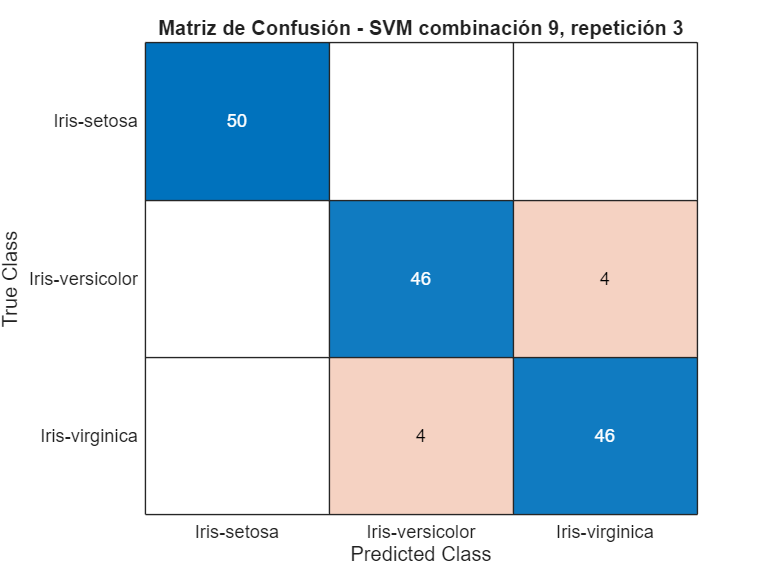

foldsSVM = prediccionesShuffleSVM{modelIdx, rep};

% Concatenar todos los folds para reconstruir la tabla completa
real_all = [];
pred_all = [];
for i = 1:length(foldsSVM)
    fold = foldsSVM{i};
    real_all = [real_all; fold.Real];
    pred_all = [pred_all; fold.Prediccion];
end

% Convertir a array de strings
real_all_str = string(real_all);
pred_all_str = string(pred_all);

% Mostrar matriz de confusión
figure;
[CM, ORDERCM] = confusionmat(real_all_str, pred_all_str);
confusionchart(real_all_str, pred_all_str);
title(sprintf('Matriz de Confusión - SVM combinación %d, repetición %d', modelIdx, rep));

### Comparaciones múltiples entre SVMs

metrics_SVM_1.Accuracy     = metricsSVM.Accuracy(:,:,1);
metrics_SVM_1.Precision    = metricsSVM.Precision(:,:,1);
metrics_SVM_1.Recall       = metricsSVM.Recall(:,:,1);
metrics_SVM_1.Specificity  = metricsSVM.Specificity(:,:,1);
metrics_SVM_1.F1Score      = metricsSVM.F1Score(:,:,1);

rep = 1;  % Solo analizamos la primera repetición
numCombinaciones = size(prediccionesShuffleSVM, 1);
numFolds = 10;  % Sabemos que cada modelo tiene 10 folds barajados
clasesUnicas = categories(categorical(iris_copy{:,5}));

% Inicializar variables
accuracy_todos = [];
grupos = [];

for modelIdx = 1:numCombinaciones
    folds = prediccionesShuffleSVM{modelIdx, rep};
    accuracies_modelo = zeros(numFolds, 1);

    for foldIdx = 1:numFolds
        fold = folds{foldIdx};
        y_real = categorical(fold.Real);
        y_pred = categorical(fold.Prediccion);

        % Accuracy por fold
        accuracies_modelo(foldIdx) = mean(y_real == y_pred);
    end

    % Acumular para Kruskal-Wallis
    accuracy_todos = [accuracy_todos; accuracies_modelo];
    grupos = [grupos; repmat(modelIdx, numFolds, 1)];
end

% Test Kruskal-Wallis
[p_kw, tabla_kw, stats_kw] = kruskalwallis(accuracy_todos, grupos, 'off');

fprintf("p-valor del test de Kruskal-Wallis sobre Accuracy por fold (rep 1): %.4e\n", p_kw);

p-valor del test de Kruskal-Wallis sobre Accuracy por fold (rep 1): 9.2887e-01



% Comparaciones múltiples post-hoc si es significativo
if p_kw < 0.05
    fprintf("Diferencias significativas detectadas entre modelos (p < 0.05):\n");
    c = multcompare(stats_kw, 'CType', 'dunn-sidak');
end


### Comparación entre todos los modelos (LDA, QDA, DecisionTree, SVM)

% Convertir clases reales a string
clasesRealesStr = string(y);

% ========== SVM1: accuracy por fold barajado ==========
foldsSVM = prediccionesShuffleSVM{1, 1};
accuracy_SVM1 = zeros(10, 1);
for i = 1:10
    datos = foldsSVM{i};
    accuracy_SVM1(i) = mean(datos.Real == datos.Prediccion);
end

% ========== Árbol simple ==========
predTree = string(prediccionesArbol(:,1));
tablaTree = table(clasesRealesStr, predTree, 'VariableNames', {'Real', 'Prediccion'});

% Barajar
rng(1); tablaTree = tablaTree(randperm(150), :);
foldsTree = mat2cell(tablaTree, repmat(15, 10, 1), 2);
accuracy_Tree = cellfun(@(t) mean(t.Real == t.Prediccion), foldsTree);

% ========== LDA ==========
predLDA = string(prediccionesLDA);
tablaLDA = table(clasesRealesStr, predLDA, 'VariableNames', {'Real', 'Prediccion'});

rng(2); tablaLDA = tablaLDA(randperm(150), :);
foldsLDA = mat2cell(tablaLDA, repmat(15, 10, 1), 2);
accuracy_LDA = cellfun(@(t) mean(t.Real == t.Prediccion), foldsLDA);

% ========== QDA ==========
predQDA = string(prediccionesCuadratic);
tablaQDA = table(clasesRealesStr, predQDA, 'VariableNames', {'Real', 'Prediccion'});

rng(3); tablaQDA = tablaQDA(randperm(150), :);
foldsQDA = mat2cell(tablaQDA, repmat(15, 10, 1), 2);
accuracy_QDA = cellfun(@(t) mean(t.Real == t.Prediccion), foldsQDA);

% ========== Unir todas las accuracies ==========
accuracy_total = [accuracy_Tree; accuracy_LDA; accuracy_QDA; accuracy_SVM1];
grupos_total = [repmat("DecisionTree", 10, 1);
                repmat("LDA", 10, 1);
                repmat("QDA", 10, 1);
                repmat("SVM", 10, 1)];

% ========== Test Kruskal-Wallis ==========
[p_kw, tabla_kw, stats_kw] = kruskalwallis(accuracy_total, grupos_total, 'off');
fprintf("\nKruskal-Wallis p = %.4e\n", p_kw);


Kruskal-Wallis p = 7.2253e-01



% Comparaciones múltiples si hay diferencia significativa
if p_kw < 0.05
    fprintf("Diferencias significativas detectadas entre modelos.\n");
    c = multcompare(stats_kw, 'CType', 'dunn-sidak');
end

% Calcular media y desviación estándar de accuracy por modelo
mean_acc_tree = mean(accuracy_Tree);
std_acc_tree = std(accuracy_Tree);

mean_acc_lda = mean(accuracy_LDA);
std_acc_lda = std(accuracy_LDA);

mean_acc_qda = mean(accuracy_QDA);
std_acc_qda = std(accuracy_QDA);

mean_acc_svm = mean(accuracy_SVM1);
std_acc_svm = std(accuracy_SVM1);

% Crear tabla resumen
modelos = ["DecisionTree"; "LDA"; "QDA"; "SVM"];
mean_accuracy = [mean_acc_tree; mean_acc_lda; mean_acc_qda; mean_acc_svm];

% Formatear SD en notación científica base 10
std_accuracy_raw = [std_acc_tree; std_acc_lda; std_acc_qda; std_acc_svm];
std_accuracy_str = arrayfun(@(x) strrep(sprintf('%.2e', x), 'e', ' × 10^'), std_accuracy_raw, 'UniformOutput', false);

% Convertir modelos a cell array de strings para que todas las columnas sean compatibles
modelos_cell = cellstr(modelos);

% Crear tabla (usando cell arrays donde es necesario)
tablaResumen = table(modelos_cell, mean_accuracy, std_accuracy_str, ...
    'VariableNames', {'Modelo', 'Mean_Accuracy', 'Std_Accuracy'});

% Mostrar tabla
disp(tablaResumen);

         Modelo         Mean_Accuracy      Std_Accuracy   
    ________________    _____________    _________________

    {'DecisionTree'}          0.96       {'5.62 × 10^-02'}
    {'LDA'         }          0.98       {'3.22 × 10^-02'}
    {'QDA'         }       0.97333       {'4.66 × 10^-02'}
    {'SVM'         }       0.95333       {'6.32 × 10^-02'}

